# Benchmark solvers for solving whole body metabolic models

**Authors: Ronan M.T. Fleming, University of Galway**

**Reviewers: **

## Introduction

Compare the time taken to solve different formulations of constraint-based modelling problems involving whole body metabolic models with different solvers and different methods for each solver with the option to repeat the analysis to compute mean and variance of solution times.

## EQUIPMENT SETUP

## **Initialize the COBRA Toolbox.**

Please ensure that The COBRA Toolbox has been properly installed, and initialized using the `initCobraToolbox` function.

if 0 %set to true if your toolbox has not been initialised
    initCobraToolbox(false) % false, as we don't want to update
end

## PROCEDURE 

Define the location to save your results

if 1
    resultsFolder = '~/drive/sbgCloud/projects/variationalKinetics/results/WBM/';
else
    resultsFolder = pwd;
end

Load whole body metabolic model - change this to suit your own setup.

modelToUse ='Harvey';
modelToUse ='Harvetta';
driver_loadBenchmarkWBMsolvers

## Define the methods (algorithms) available for different solvers

% CPLEX
% 0	CPX_ALG_AUTOMATIC 	Automatic: let CPLEX choose; default
% 1	CPX_ALG_PRIMAL 	Primal simplex
% 2	CPX_ALG_DUAL 	Dual simplex
% 3	CPX_ALG_NET 	Network simplex
% 4	CPX_ALG_BARRIER 	Barrier
% 5	CPX_ALG_SIFTING 	Sifting
% 6	CPX_ALG_CONCURRENT 	Concurrent (Dual, Barrier, and Primal in opportunistic parallel mode; Dual and Barrier in deterministic parallel mode)
%https://www.ibm.com/docs/en/icos/12.10.0?topic=parameters-algorithm-continuous-linear-problems
cplexLPMethods ={'AUTOMATIC','PRIMAL','DUAL','NETWORK','BARRIER','SIFTING','CONCURRENT'};
% 0	CPX_ALG_AUTOMATIC	Automatic: let CPLEX choose; default
% 1	CPX_ALG_PRIMAL	Use the primal simplex optimizer.
% 2	CPX_ALG_DUAL	Use the dual simplex optimizer.
% 3	CPX_ALG_NET	Use the network optimizer.
% 4	CPX_ALG_BARRIER	Use the barrier optimizer.
% 6	CPX_ALG_CONCURRENT	Use the concurrent optimizer.
% https://www.ibm.com/docs/en/icos/12.10.0?topic=parameters-algorithm-continuous-quadratic-optimization
cplexQPMethods ={'AUTOMATIC','PRIMAL','DUAL','NETWORK','BARRIER','CONCURRENT'};

% Mosek

% MSK_IPAR_OPTIMIZER
%    The parameter controls which optimizer is used to optimize the task.
%    Default "FREE"
%    Accepted "FREE", "INTPNT", "CONIC", "PRIMAL_SIMPLEX", "DUAL_SIMPLEX", "FREE_SIMPLEX", "MIXED_INT"
%    Example param.MSK_IPAR_OPTIMIZER = 'MSK_OPTIMIZER_FREE'
mosekMethods ={'MSK_OPTIMIZER_FREE', 'MSK_OPTIMIZER_INTPNT', 'MSK_OPTIMIZER_CONIC', 'MSK_OPTIMIZER_PRIMAL_SIMPLEX', 'MSK_OPTIMIZER_DUAL_SIMPLEX', 'MSK_OPTIMIZER_FREE_SIMPLEX'};

% Gurobi
% https://www.gurobi.com/documentation/current/refman/method.html
% Algorithm used to solve continuous models
% Algorithm used to solve continuous models or the initial root relaxation of a MIP model. Options are:
gurobiLPMethods = {'AUTOMATIC','PRIMAL','DUAL','BARRIER','CONCURRENT','DETERMINISTIC_CONCURRENT'};
gurobiQPMethods = {'AUTOMATIC','PRIMAL','DUAL','BARRIER'};

## Set  parameters for benchmark

COBRA toolbox parameters

printLevel=1; %  {(0),1,2} 1 output from optimiseVKmode, 2 also output from solver
changeOK = changeCobraSolverParams('LP', 'printLevel', printLevel);
feasTol=1e-6;
changeOK = changeCobraSolverParams('LP', 'printLevel', feasTol);

Select whether to compare one or a set of solvers

compareSolvers = 1;

Select whether to compare one or a set of different formulations of constraint-based modelling problems involving whole body metabolic models.

compareSolveWBMmethods = 1;

Select whether to compare one or a set of available methods (algorithms) for each solver

compareSolverMethods = 0;

Define the number of times to replicate the same formulation, solver, method combination.

nReplicates = 1;

Set the maximum time limit allowed to solve a single instance. Useful for eliminating slow instances in a large batch of trials.

secondsTimeLimit = 30;

#### Display and (optionally) modify properties of the whole body model that may effect solve time

[nMet,nRxn]=size(model.S)

nMet = 58095

nRxn = 83395

Identify large bounds not at the maximum

boundMagnitudes = [abs(model.lb);abs(model.ub)];
largestMagnitudeBound = max(boundMagnitudes);
fprintf('%g%s\n',(nnz(largestMagnitudeBound==[abs(model.lb);abs(model.ub)])*100)/(length(model.lb)*2),' = percent of bounds at maximum')

62.2112 = percent of bounds at maximum


Display bounds that are not at the maximum

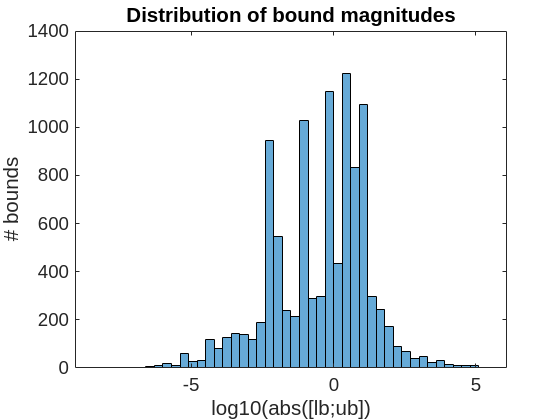

if 1
    figure
    histogram(log10(boundMagnitudes(boundMagnitudes~=largestMagnitudeBound & boundMagnitudes~=0)))
    xlabel('log10(abs([lb;ub])')
    ylabel('# bounds')
    title('Distribution of bound magnitudes')
end

Replace large bounds with inf or -inf. This is a good idea. Better to leave this option on.

if 1
    model.lb(-largestMagnitudeBound==model.lb)=-inf;
    model.ub(largestMagnitudeBound==model.ub)= inf;
end
boolMagnitudes = boundMagnitudes~=largestMagnitudeBound & boundMagnitudes~=0 & boundMagnitudes<1e-4;
boolRxns = boolMagnitudes(1:nRxn) | boolMagnitudes(nRxn+1:2*nRxn);

Optionally, print the bounds for reactions with small magnitude

if 0
    printFluxBounds(model,model.rxns(boolRxns))
end
fprintf('%g%s\n',nnz(boolRxns)*100/length(boolRxns),' = percent of bounds with magnutide less than 1e-4')

0.389712 = percent of bounds with magnutide less than 1e-4


Optionally, print the bounds for reactions with small difference

boundDifference = model.ub - model.lb;
bool = length(model.rxns);
Z = table(boundDifference,model.rxns,model.rxnNames,'VariableNames',{'boundDifference','rxns','rxnNames'});
if any(boundDifference<0)
    error(['lb > ub for ' num2str(nnz(boundDifference)) ' reactions'])
end
boolDifference = boundDifference<1e-5 & boundDifference~=0;
Z = sortrows(Z(boolDifference,:),'boundDifference');
if 0
    printFluxBounds(model,Z.rxns,1)
end
fprintf('%g%s\n',nnz(boolRxns)*100/length(boolRxns), ' = percent of bounds with difference (ub - lb) less than 1e-5')

0.389712 = percent of bounds with difference (ub - lb) less than 1e-5



forwardBoolDifference = boolDifference & model.lb>=0 & model.ub>0;
reverseBoolDifference = boolDifference & model.lb<0 & model.ub<=0;
reversibleBoolDifference = boolDifference & model.lb<0 & model.ub>0;

if any((forwardBoolDifference | reverseBoolDifference | reversibleBoolDifference)~=boolDifference)
    error('missing bool difference')
end

Optionally relax bounds that are very tight

relaxTightBounds = 0;
if relaxTightBounds
    modelOld=model;
    done=false(nRxn,1);
    for x=higherExponent:-1:lowerExponent
        %calulate the difference between the bounds each time
        boundDifference = model.ub - model.lb;

        %forward
        bool = forwardBoolDifference & (boundDifference <= 10^(-x));
        model.ub(bool & ~done) = model.ub(bool & ~done)*(10^(x-lowerExponent+1));
        done = done | bool;

        %reverse
        bool = reverseBoolDifference & (boundDifference <= 10^(-x));
        model.lb(bool & ~done) = model.lb(bool & ~done)*(10^(x-lowerExponent+1));
        done = done | bool;

        %reversible
        bool = reversibleBoolDifference & (boundDifference <= 10^(-x));
        model.lb(bool & ~done) = model.lb(bool & ~done)*(10^((x-lowerExponent+1)/2));
        model.ub(bool & ~done) = model.ub(bool & ~done)*(10^((x-lowerExponent+1)/2));
        done = done | bool;

        %reset
        %done=false(nRxn,1);
    end
    if 1
        printFluxBounds(model,Z.rxns,1)
    end
end

## Prepare a benchmark table, choose the solver and solve

VariableNames={'interface','solver','method','problem','model','stat','origStat','time','f','f1','f2','f0'};
% Define the corresponding variable types
VariableTypes = {'string', 'string', 'string','string','string','double','string','double','double','double','double','double'};
T = table('Size', [0 length(VariableNames)],'VariableNames',VariableNames,'VariableTypes', VariableTypes);


Select the solvers to compare

if compareSolvers
    solvers = { 'gurobi','ibm_cplex','mosek'};
    %solvers = { 'ibm_cplex','mosek','gurobi'};
    %solvers = { 'mosek','ibm_cplex','gurobi'};
else
    % Choose the solver
    % solvers = {'gurobi'};
    solvers = {'ibm_cplex'};
    % solvers = {'mosek'};
end

Select the formulations to compare

if compareSolveWBMmethods
    %solveWBMmethods = {'LP','QP','QRLP','QRQP','zero','oneInternal'};
    solveWBMmethods = {'LP','QP'};%,'zero','oneInternal'};
    %solveWBMmethods = {'LP','oneInternal'};
else
    % Choose type of problem to solve
    % solveWBMmethods = {'LP'};
    solveWBMmethods = {'QP'};
    %solveWBMmethods = {'QRLP'};
    %solveWBMmethods = {'QRQP'};
end

Set the min norm weight for QP problems

minNormWeight = 1e-4;
%model.c(:)=0;

Solve the ensemble of instances

for ind = 1:nReplicates
    for i = 1:length(solveWBMmethods)
        solveWBMmethod = solveWBMmethods{i};
        for j = 1:length(solvers)
            solver = solvers{j};

            clear param;
            param.printLevel=0;
            param.timelimit=secondsTimeLimit;
            param.solver=solver;

            switch solveWBMmethod
                case 'LP'
                    param.solveWBMmethod='LP';
                    param.minNorm = 0;
                    param.solver=solver;
                case 'QP'
                    param.solveWBMmethod='QP';
                    param.minNorm = minNormWeight;
                case 'QRLP'
                    param.solveWBMmethod='QRLP';
                    param.minNorm = 0;
                case 'QRQP'
                    param.solveWBMmethod='QRQP';
                    param.minNorm = minNormWeight;
                case 'zero'
                    param.solveWBMmethod='zero';
                    param.minNorm = 'zero';
                case 'oneInternal'
                    param.solveWBMmethod='oneInternal';
                    if isfield(model,'SConsistentRxnBool')
                        param.minNorm = 'oneInternal';
                    else
                        error('param.solveWBMmethod= oneInternal cannot be implemented as model.SConsistentRxnBool is missing')
                    end
            end

            switch solver
                case 'gurobi'
                    % Model scaling
                    %  	Type:	int
                    %  	Default value:	-1
                    %  	Minimum value:	-1
                    %  	Maximum value:	3
                    % Controls model scaling. By default, the rows and columns of the model are scaled in order to improve the numerical
                    % properties of the constraint matrix. The scaling is removed before the final solution is returned. Scaling typically
                    % reduces solution times, but it may lead to larger constraint violations in the original, unscaled model. Turning off
                    % scaling (ScaleFlag=0) can sometimes produce smaller constraint violations. Choosing a different scaling option can
                    % sometimes improve performance for particularly numerically difficult models. Using geometric mean scaling (ScaleFlag=2)
                    % is especially well suited for models with a wide range of coefficients in the constraint matrix rows or columns.
                    % Settings 1 and 3 are not as directly connected to any specific model characteristics, so experimentation with both
                    % settings may be needed to assess performance impact.
                    param.scaleFlag=0;

                case 'ibm_cplex'
                    % https://www.ibm.com/docs/en/icos/12.10.0?topic=infeasibility-coping-ill-conditioned-problem-handling-unscaled-infeasibilities
                    param.minNorm = 0;

                    % Decides how to scale the problem matrix.
                    % Value  Meaning
                    % -1	No scaling
                    % 0	Equilibration scaling; default
                    % 1	More aggressive scaling
                    % https://www.ibm.com/docs/en/icos/12.10.0?topic=parameters-scale-parameter
                    param.scaind = -1;

                    % Emphasizes precision in numerically unstable or difficult problems.
                    % This parameter lets you specify to CPLEX that it should emphasize precision in
                    % numerically difficult or unstable problems, with consequent performance trade-offs in time and memory.
                    % Value Meaning
                    % 0   Do not emphasize numerical precision; default
                    % 1	Exercise extreme caution in computation
                    % https://www.ibm.com/docs/en/icos/12.10.0?topic=parameters-numerical-precision-emphasis
                    param.emphasis_numerical=1;
                case 'mosek'
                    param.MSK_DPAR_OPTIMIZER_MAX_TIME=secondsTimeLimit;
                    param.MSK_IPAR_WRITE_DATA_PARAM='MSK_ON';
                    param.MSK_IPAR_LOG_INTPNT=10;
                    param.MSK_IPAR_LOG_PRESOLVE=10;

                    % MSK_IPAR_INTPNT_SCALING
                    % Controls how the problem is scaled before the interior-point optimizer is used.
                    % Default
                    % "FREE"
                    % Accepted
                    % "FREE", "NONE"
                    % param..MSK_IPAR_INTPNT_SCALING = 'MSK_SCALING_FREE';
                    param.MSK_IPAR_INTPNT_SCALING='MSK_SCALING_NONE';

                    % MSK_IPAR_SIM_SCALING
                    % Controls how much effort is used in scaling the problem before a simplex optimizer is used.
                    % Default
                    % "FREE"
                    % Accepted
                    % "FREE", "NONE"
                    % Example
                    % param.MSK_IPAR_SIM_SCALING = 'MSK_SCALING_FREE'
                    param.MSK_IPAR_SIM_SCALING='MSK_SCALING_NONE';

                    % MSK_IPAR_SIM_SCALING_METHOD
                    % Controls how the problem is scaled before a simplex optimizer is used.
                    % Default
                    % "POW2"
                    % Accepted
                    % "POW2", "FREE"
                    % Example
                    % param.MSK_IPAR_SIM_SCALING_METHOD = 'MSK_SCALING_METHOD_POW2'
                    % param.MSK_IPAR_SIM_SCALING_METHOD='MSK_SCALING_METHOD_FREE';
            end

            if compareSolverMethods
                % Solve a problem with selected solver and each method available to that solver
                % solveWBMmethod = {'LP','QP','QRLP','QRQP','zero','oneInternal'};
                switch param.solveWBMmethod
                    case {'LP','zero','oneInternal'}
                        switch solver
                            case 'gurobi'
                                solverMethods = gurobiLPMethods;
                            case 'ibm_cplex'
                                solverMethods = cplexLPMethods;
                            case 'mosek'
                                solverMethods = mosekMethods;
                        end
                    case {'QP','QRLP','QRQP'}
                        switch solver
                            case 'gurobi'
                                solverMethods = gurobiQPMethods;
                            case 'ibm_cplex'
                                solverMethods = cplexQPMethods;
                            case 'mosek'
                                solverMethods = mosekMethods;
                        end
                end
                for k=1:length(solverMethods)
                    switch solver
                        case 'gurobi'
                            param.lpmethod=solverMethods{k};
                            param.qpmethod=solverMethods{k};
                        case 'ibm_cplex'
                            param.lpmethod=solverMethods{k};
                            param.qpmethod=solverMethods{k};
                        case 'mosek'
                            %https://docs.mosek.com/latest/toolbox/parameters.html#mosek.iparam.optimizer
                            %The parameter controls which optimizer is used to optimize the task.
                            param.MSK_IPAR_OPTIMIZER=solverMethods{k};
                    end

                    tic
                    solution = optimizeCbModel(model,'min', param.minNorm,1,param);
                    T = [T; {'optimizeCbModel', solver, solverMethods{k}, param.solveWBMmethod, modelToUse, solution.stat,{solution.origStat},toc,{solution.f},{solution.f1},{solution.f2},{solution.f0}}];
                    %display(T)
                end
            else
                % Solve a problem with selected solver and one method available to that solver
                switch solver
                    case 'gurobi'
                        param.lpmethod='BARRIER';
                        param.qpmethod='AUTOMATIC';
                        method = param.lpmethod;
                    case 'ibm_cplex'
                        param.lpmethod='BARRIER';
                        param.qpmethod='BARRIER';
                        method = param.lpmethod;
                    case 'mosek'
                        method = 'FREE';
                        method = 'INTPNT';
                        param.MSK_IPAR_OPTIMIZER=['MSK_OPTIMIZER_' method];
                        
                end
                tic
                solution = optimizeCbModel(model,'min', param.minNorm,1,param);
                T = [T; {'optimizeCbModel', solver, method, param.solveWBMmethod, modelToUse, solution.stat,{solution.origStat},toc,{solution.f},{solution.f1},{solution.f2},{solution.f0}}];
            end
        end
    end
end


Interrupt request received


T.method = replace(T.method,'MSK_OPTIMIZER_','');
T.method = replace(T.method,'_',' ');
T.solver = replace(T.solver,'ibm_','');
T.approach = append(T.solver, ' ', T.method);
T =sortrows(T,{'stat','time'},{'ascend','ascend'});
display(T)

save([resultsFolder 'results_benchmarkWBMsolvers.mat'],'T')

if 1
    if 0
        % Create the first histogram
        histogram(T.time(T.stat==1 & strcmp(T.problem,'LP')),'NumBins',100,'FaceColor', 'r','FaceAlpha', 0.5);  % 'r' sets the color to red
        hold on;  % Keep the current plot so that the second histogram is overlaid

        % Create the second histogram
        histogram(T.time(T.stat==1 & strcmp(T.problem,'QP')),'NumBins',100,'FaceColor', 'b','FaceAlpha', 0.5);  % 'r' sets the color to red
        xlabel({'Whole body metabolic model LP solution time (seconds)',[int2str(nMet) ' metabolites, ' int2str(nRxn) ' reactions.']})
        ylabel('Number of solutions')
        title('Solution time depends on solver, method and problem');
        legend('LP', 'QP');
        hold off;  % Release the hold for future plots

    else
        if ~exist('T0','var')
            T0 = T;
        else
            T = T0;
        end
        figure
        % Concatenate solver and method into 'approach'
        T.approach = append(T.solver, ' ', T.method);

        T = T(strcmp(T.problem,'LP'),:);
        % Calculate the mean solve time and standard deviation for each approach
        avg_times = varfun(@mean, T, 'InputVariables', 'time', 'GroupingVariables', 'approach');
        std_times = varfun(@std, T, 'InputVariables', 'time', 'GroupingVariables', 'approach');

        times = avg_times;
        times.std_time = std_times.std_time;
        % Sort both the avg_times and std_times by the mean solve time
        [times, sort_idx] = sortrows(times, 'mean_time');

        % Create a bar plot with the sorted data
        b = bar(times.mean_time, 'FaceColor', 'b', 'FaceAlpha', 0.5);
        hold on;

        % Add error bars using the sorted standard deviations
        errorbar(times.mean_time, times.std_time, 'k', 'linestyle', 'none', 'LineWidth', 1.5);
        xticks(1:length(times.approach))
        xticklabels(times.approach)

        % Add labels and title
        xlabel('Approach', 'Interpreter', 'none');
        ylabel('Solve Time (s)');
        title('LP solve times', 'Interpreter', 'none');

        figure
        % fastest times 
        times = times(times.mean_time<mean(times.mean_time),:);
        % Create a bar plot with the sorted data
        b = bar(times.mean_time, 'FaceColor', 'b', 'FaceAlpha', 0.5);
        hold on;

        % Add error bars using the sorted standard deviations
        errorbar(times.mean_time, times.std_time, 'k', 'linestyle', 'none', 'LineWidth', 1.5);
        xticks(1:length(times.approach))
        xticklabels(times.approach)

        % Add labels and title
        xlabel('Approach', 'Interpreter', 'none');
        ylabel('Solve Time (s)');
        title('LP solve times', 'Interpreter', 'none');

        
        T = T0;
        figure
        T = T(strcmp(T.problem,'QP'),:);
        % Calculate the mean solve time and standard deviation for each approach
        avg_times = varfun(@mean, T, 'InputVariables', 'time', 'GroupingVariables', 'approach');
        std_times = varfun(@std, T, 'InputVariables', 'time', 'GroupingVariables', 'approach');

        times = avg_times;
        times.std_time = std_times.std_time;
        % Sort both the avg_times and std_times by the mean solve time
        [times, sort_idx] = sortrows(times, 'mean_time');

        % Create a bar plot with the sorted data
        b = bar(times.mean_time, 'FaceColor', 'r', 'FaceAlpha', 0.5);
        hold on;

        % Add error bars using the sorted standard deviations
        errorbar(times.mean_time, times.std_time, 'k', 'linestyle', 'none', 'LineWidth', 1.5);
        xticks(1:length(times.approach))
        xticklabels(times.approach)

        % Add labels and title
        xlabel('Approach', 'Interpreter', 'none');
        ylabel('Solve Time (seconds)');
        title('QP solve times', 'Interpreter', 'none');

        T = T0;
        figure
        % fastest times 
        times = times(times.mean_time<mean(times.mean_time),:);
        % Create a bar plot with the sorted data
        b = bar(times.mean_time, 'FaceColor', 'r', 'FaceAlpha', 0.5);
        hold on;
        % Add error bars using the sorted standard deviations
        errorbar(times.mean_time, times.std_time, 'k', 'linestyle', 'none', 'LineWidth', 1.5);
        xticks(1:length(times.approach))
        xticklabels(times.approach)

        % Add labels and title
        xlabel('Approach', 'Interpreter', 'none');
        ylabel('Solve Time (seconds)');
        title('QP solve times', 'Interpreter', 'none');
    end
end